cell_num = 135

cell_num = 135

log_area = log(data(cell_num,:,2));
div_threshold = 0.2;
max_gr = 0.05;

Plot of log area for a mother cells growth

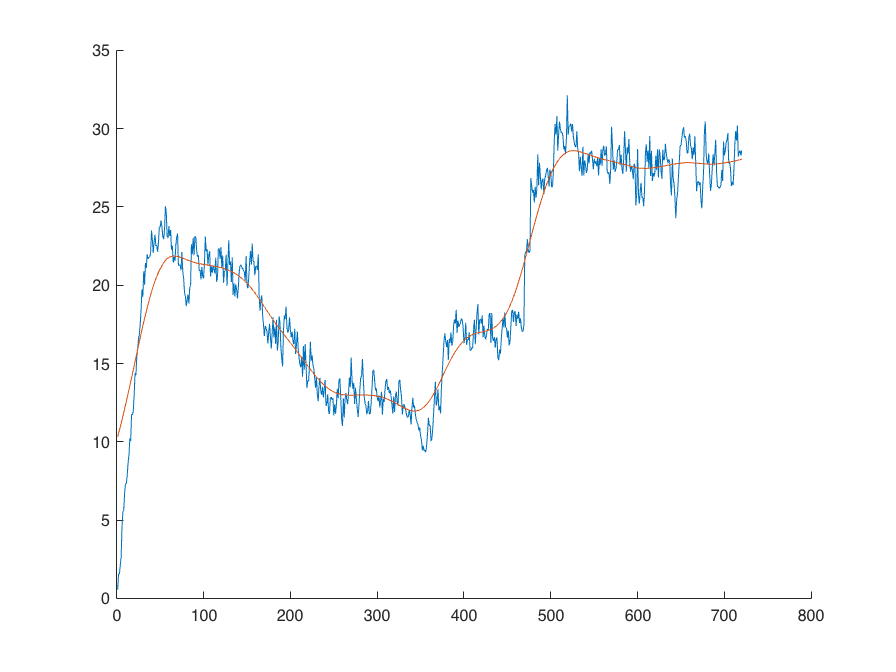

div_threshold = 0.2;
gr = diff(log_area);
gr(abs(gr)>div_threshold)=0;
csum = cumsum(gr);
lagt = (0:719) - cumsum(gr)/max_gr;
x = 0:719;
smooth_lagt =  smoothdata(lagt,'gaussian',100);
clf
hold on 
plot(lagt)
plot(smooth_lagt)
hold off

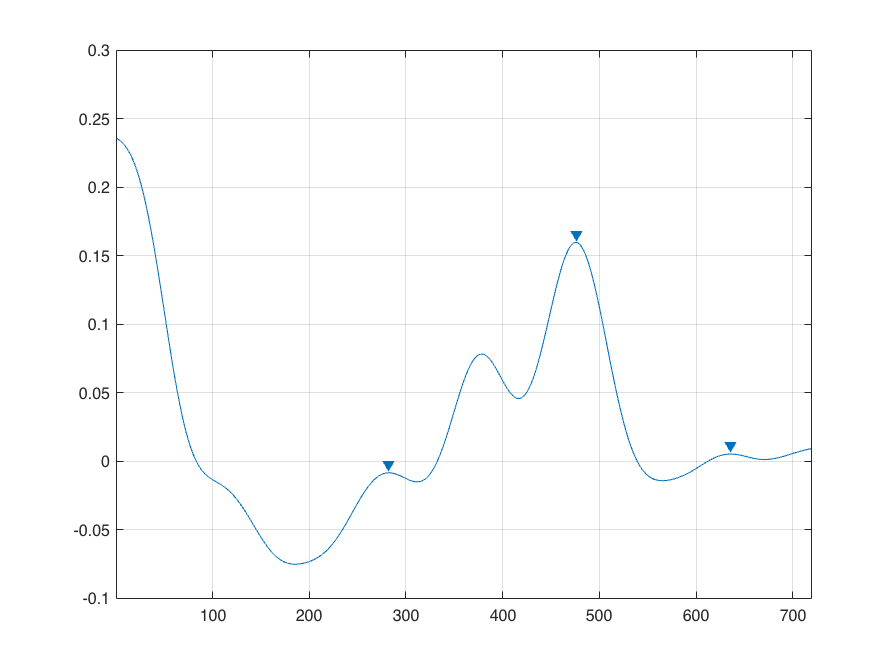

clf
lap = smoothdata(diff(smooth_lagt),'gaussian',100);
findpeaks(lap,"SortStr",'descend','MinPeakDistance',100)